## P de defeito em torneiras

7.

p_defeito = 0.3;
n = 5; % amostras
k = 3; % defeitos
N = 1e6;

a)

[p_3_defeitos_p,amostragem] = prob_simulation(p_defeito,n,k,N);
p_3_defeitos_t = nchoosek(n,k) * (p_defeito^k)*(1-p_defeito)^(n-k);
fprintf('Probabilidade de %d defeitos:\n -Prática = %.3f\n -Teórica = %.3f',k, p_3_defeitos_p, p_3_defeitos_t)

Probabilidade de 3 defeitos:
 -Prática = 0.309
 -Teórica = 0.132

c) histograma

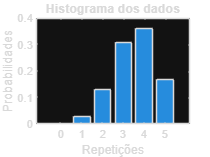

bar(amostragem(:,1), amostragem(:,2));
title("Histograma dos dados");
xlabel("Repetições");
ylabel("Probabilidades")